clear
clc

## Variables

% Main Sim variables

Insulation_thickness=5; % mm
Air_thickness=1.5; % mm actually 1.46mm
Wall_thickness=5.5; % mm actually 5.49mm

dx=0.1;

Sim_time=500; % s
dt=0.001;

Tinf=3000;

% Conduction Variables/ Wall Material Variables

alpha_wall=4.2; % mm^2/s
alpha_insulation=0.1; % mm^2/s
alpha_air=0.001; % mm^2/s
c=0.5*1000; % J/(kg-K)
rho=8000/(1000^3); % kg/mm^3

% Vacuum Radiation Variables

emiss_alumina=0.8;
emiss_air=0.8;
emiss_steel=0.4;

boltz=5.67e-8/(1000^2); % J/(s-mm^2-K)

% Radiation from reaction products to insualtion variables

emiss_r_Tinf=0.2; % change this
emiss_g_Twall=0.4; % supposed to be steel or not?
emiss_e=emiss_alumina/(1-(1-emiss_alumina)*(1-emiss_r_Tinf));

% Bartz Method Variables

gamma=1.176;
T0c=3000;
M=0.0438;

D_t=17.6; % mm
D_t=D_t/25.4; % inch
Pr=0.4939; % maybe not the same as the other prandtl number
Pr0_inf=0.4939;
mu0_inf=9.691e-8; % kg/(mm-s)
mu0_inf=mu0_inf*55.9974; % lb/(inch-s)
Cp0_inf=3.3334*1000; % J/(kg-K)
Cp0_inf=Cp0_inf/4186.8; % BTU/(lb-Fahrenheit)
p0_c=(30*10^5)/6895; % lb/(inch)^2
cstar=1095*1000; % mm/s
cstar=cstar/25.4; % inch/s
R=13.2; % mm
R=R/25.4; % inch
At=pi*(17.6^2)/4; % mm^2 
A=pi*(65^2)/4; % mm^2

## Calculation


% Matrices initialisation
[Insulation_X,Insulation_t]=meshgrid(0:dx:Insulation_thickness,0:dt:Sim_time);
[Air_X,Air_t]=meshgrid(0:dx:Air_thickness,0:dt:Sim_time);
[Wall_X,Wall_t]=meshgrid(0:dx:Wall_thickness,0:dt:Sim_time);

Insulation_T=300.*ones([size(Insulation_t,1),size(Insulation_X,2)]);
Air_T=300.*ones([size(Air_t,1),size(Air_X,2)]);
Wall_T=300.*ones([size(Wall_t,1),size(Wall_X,2)]);

Insulation_dTdt=zeros([size(Insulation_t,1),size(Insulation_X,2)]);
Air_dTdt=zeros([size(Air_t,1),size(Air_X,2)]);
Wall_dTdt=zeros([size(Wall_t,1),size(Wall_X,2)]);

Insulation_d2Tdx2=zeros([size(Insulation_t,1),size(Insulation_X,2)]);
Air_d2Tdx2=zeros([size(Air_t,1),size(Air_X,2)]);
Wall_d2Tdx2=zeros([size(Wall_t,1),size(Wall_X,2)]);

for i=1:(size(Insulation_t,1)-1)
    for j=1:size(Insulation_X,2) % For insulation
        if j==1
            % Bartz Method
            sigma=((0.5*(Insulation_T(i,j)/T0c)*(1+0.5*(gamma-1)*M^2)+0.5)^(-0.68))*(1+0.5*(gamma-1)*M^2)^(-0.12);
            alpha_T=((0.026/(D_t^0.2))*(((mu0_inf^0.2)*Cp0_inf)/(Pr0_inf^0.6))*((p0_c/cstar)^(0.8))*((D_t/R)^(0.1)))*((At/A)^(0.9))*sigma;
            alpha_T=alpha_T*(1/(1.8956/3600))*(1/25.4)^2;
            Te=T0c*((1+(Pr^0.33)*0.5*(gamma-1)*M^2)/(1+0.5*(gamma-1)*M^2));
            
            Insulation_d2Tdx2(i,j)=(-Insulation_T(i,j)+Insulation_T(i,j+1))/(dx^2);
            Insulation_dTdt(i,j)=alpha_wall*Insulation_d2Tdx2(i,j)+(1/(dx*rho*c))*(emiss_e*boltz*((emiss_r_Tinf*Tinf^4-emiss_g_Twall*Insulation_T(i,j)^4))+alpha_T*(Te-Insulation_T(i,j)));
            Insulation_T(i+1,j)=Insulation_T(i,j)+dt*Insulation_dTdt(i,j);
            
        elseif j==size(Insulation_X,2)
            Insulation_d2Tdx2(i,j)=(Insulation_T(i,j-1)-Insulation_T(i,j))/(dx^2);
            Insulation_dTdt(i,j)=alpha_wall*Insulation_d2Tdx2(i,j)-(1/(dx*rho*c))*emiss_steel*boltz*Insulation_T(i,j)^4;
            Insulation_T(i+1,j)=Insulation_T(i,j)+dt*Insulation_dTdt(i,j);
            
        else
            Insulation_d2Tdx2(i,j)=(Insulation_T(i,j-1)-2*Insulation_T(i,j)+Insulation_T(i,j+1))/(dx^2);
            Insulation_dTdt(i,j)=alpha_wall*Insulation_d2Tdx2(i,j);
            Insulation_T(i+1,j)=Insulation_T(i,j)+dt*Insulation_dTdt(i,j);
        end
    end
end


## Plot figures

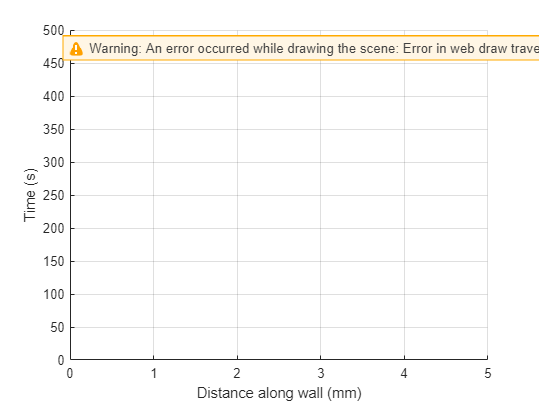

figure
surf(Insulation_X,Insulation_t,Insulation_T,'LineStyle','none')
view(2)
xlabel('Distance along wall (mm)')
ylabel('Time (s)')
zlabel('Temperature (K)')

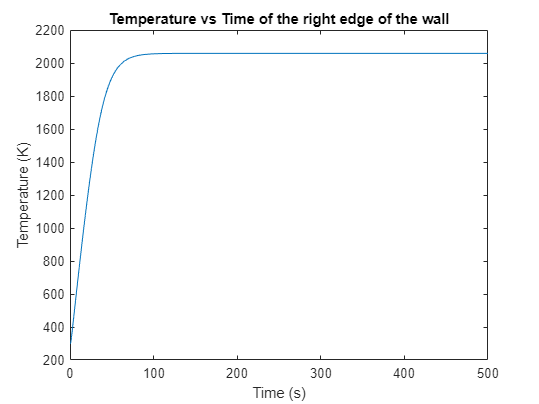


figure
plot(Insulation_t(:,end),Insulation_T(:,end))
xlabel('Time (s)')
ylabel('Temperature (K)')
title('Temperature vs Time of the right edge of the wall')

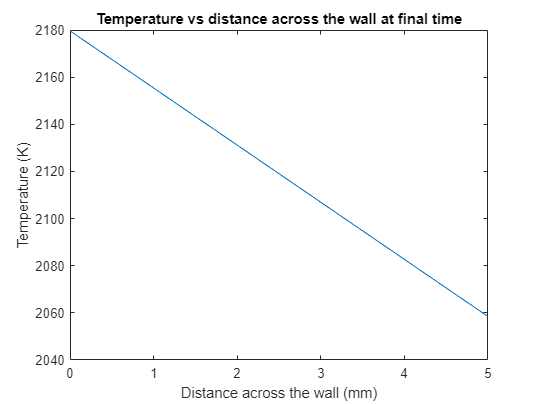


figure
plot(Insulation_X(end,:),Insulation_T(end,:))
xlabel('Distance across the wall (mm)')
ylabel('Temperature (K)')
title('Temperature vs distance across the wall at final time')